% trying waterfall plots 2 - https://uk.mathworks.com/matlabcentral/answers/514641-how-can-i-plot-a-3d-waterfall

T = sensor_data;

kgrid.t_array

ans = 1.0e-03 *

         0    0.0003    0.0006    0.0008    0.0011    0.0014    0.0017    0.0019    0.0022    0.0025    0.0028    0.0030    0.0033    0.0036    0.0039    0.0041    0.0044    0.0047    0.0050    0.0052    0.0055    0.0058    0.0061    0.0063    0.0066    0.0069    0.0072    0.0074    0.0077    0.0080    0.0083    0.0085    0.0088    0.0091    0.0094    0.0097    0.0099    0.0102    0.0105    0.0108    0.0110    0.0113    0.0116    0.0119    0.0121    0.0124    0.0127    0.0130    0.0132    0.0135


1:size(T,2)

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


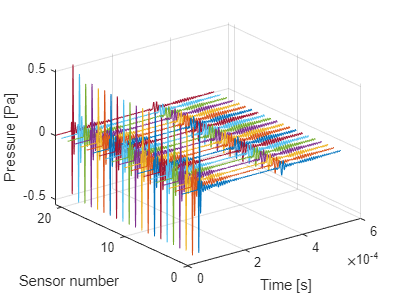



[y,x] = meshgrid(1:size(T,1), kgrid.t_array);  % T is your table
z = T(:,:); 
plot3(x,y,z);
xlabel('Time [s]'); % time
ylabel('Sensor number'); % sensor number
zlabel('Pressure [Pa]'); % amplitude
grid on


% gca().DataAspectRatio
% 
% daspect([1 35000 2000]);

% trying waterfall plots

[X,Y] = meshgrid(-3:.125:3);
Z = peaks(X,Y);
waterfall(Z)